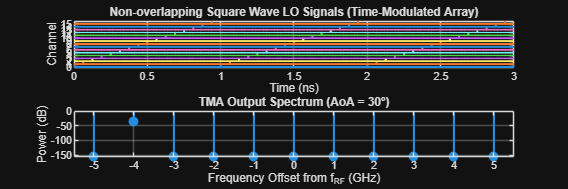

% Time-Modulated Array (TMA) Simulation
clear; close all; clc;

%% Parameters
N = 16; % Number of channels
f_RF = 28e9; % RF frequency (28 GHz)
f_TM = 1e9; % Time modulation frequency (1 GHz)
T_TM = 1/f_TM; % Modulation period
c = 3e8; % Speed of light
lambda = c/f_RF; % Wavelength
d = lambda/2; % Element spacing (half-wavelength)

% Simulation parameters
fs = 2000*f_TM; % Sampling frequency
t = 0:1/fs:10*T_TM; % Time vector
theta_scan = -90:0.5:90; % Angle range for beam patterns

%% Generate Time-Modulation Waveforms
tau = T_TM/N; % Progressive time delay
duty_cycle = 0.001; % Duty cycle for each channel

% Create non-overlapping square waves for each channel
LO_signals = zeros(N, length(t));
for n = 0:N-1
    % Each channel's square wave is delayed by n*tau
    phase_offset = n * tau;
LO_signals(n+1,:) = square(2*pi*f_TM*(t - phase_offset), duty_cycle*100) > 0;
end
% --- Comb-like (HM-LO) waveform ---
% Built by summing harmonics with EQUAL amplitude (flat spectrum)
% This is what the paper proposes in Section V to fix harmonic loss
% num_comb_harmonics = 10; % Number of harmonics to include
% LO_comb = zeros(N, length(t));
% for n = 0:N-1
%     phase_offset = n * tau;
%     comb_signal = zeros(1, length(t));
%     for m = 1:num_comb_harmonics
%         % Each harmonic has equal weight (1/num_comb_harmonics for normalization)
%         comb_signal = comb_signal + (1/num_comb_harmonics) * ...
%             cos(2*pi*m*f_TM*(t - phase_offset));
%     end
%     % Normalize to [0, 1]
%     comb_signal = comb_signal - min(comb_signal);
%     comb_signal = comb_signal / max(comb_signal);
%     LO_comb(n+1,:) = comb_signal;
% end

%% Figure 5(a) - Visualize the Time-Modulation Scheme
figure('Position', [100 100 1200 400]);
subplot(2,1,1);
for n = 1:N
plot(t*1e9, LO_signals(n,:) + (n-1)*1.5, 'LineWidth', 1.5);
hold on;
end
xlabel('Time (ns)');
ylabel('Channel');
title('Non-overlapping Square Wave LO Signals (Time-Modulated Array)');
grid on;
ylim([-0.5 N*1.5]);
yticks(0:1.5:(N-1)*1.5);
yticklabels(arrayfun(@num2str, 0:N-1, 'UniformOutput', false));
xlim([0 3*T_TM*1e9]);

%% Simulate RF Signal Reception at Different Angles
num_harmonics = 5; % Number of harmonics to analyze
m_values = -num_harmonics:num_harmonics; % Harmonic indices

% Initialize output spectrum
IF_frequencies = f_RF + m_values * f_TM;

% Simulate for a specific angle of arrival (example: 30 degrees)
theta_aoa = 30; % Angle of arrival in degrees
theta_rad = theta_aoa * pi/180;

% Calculate phase shift across array due to spatial angle
phase_spatial = @(n, freq) 2*pi * n * d * sin(theta_rad) / (c/freq);

% Simulate array output for each harmonic
output_spectrum = zeros(size(m_values));

for idx = 1:length(m_values)
m = m_values(idx);
f_IF = IF_frequencies(idx);
% Calculate array factor at this frequency
% Phase contribution: spatial + time-modulation
array_sum = 0;
for n = 0:N-1
% Phase from true-time delay and modulation
phase_tm = 2*pi * m * f_TM * n * tau;
% Phase from spatial angle
phase_sp = phase_spatial(n, f_RF);
% Total phase
total_phase = phase_tm + phase_sp;
% Fourier coefficient of square wave at harmonic m
if m == 0
beta_m = duty_cycle;
else
beta_m = sin(pi*m*duty_cycle)/(pi*m);
end
array_sum = array_sum + beta_m * exp(1j * total_phase);
end
output_spectrum(idx) = abs(array_sum)^2;
end

%% Figure 5(b) - Output Spectrum
subplot(2,1,2);
stem((IF_frequencies - f_RF)/1e9, 10*log10(output_spectrum + eps), 'filled', 'LineWidth', 1.5);
xlabel('Frequency Offset from f_{RF} (GHz)');
ylabel('Power (dB)');
title(sprintf('TMA Output Spectrum (AoA = %d°)', theta_aoa));
grid on;
xlim([min(m_values)*f_TM/1e9 - 0.5, max(m_values)*f_TM/1e9 + 0.5]);


%% Spatial-to-Spectral Mapping: Beam Patterns at Each Frequency
figure('Position', [100 600 1200 600]);

% For each harmonic, compute the beam pattern
colors = lines(length(m_values));
for idx = 1:length(m_values)
m = m_values(idx);
f_IF = IF_frequencies(idx);
% Skip DC component for clarity
if m == 0
continue;
end
% Calculate beam pattern
beam_pattern = zeros(size(theta_scan));
for theta_idx = 1:length(theta_scan)
theta_deg = theta_scan(theta_idx);
theta_r = theta_deg * pi/180;
array_sum = 0;
for n = 0:N-1
% Phase from true-time delay
phase_tm = 2*pi * m * f_TM * n * tau;
% Phase from spatial angle
phase_sp = 2*pi * n * d * sin(theta_r) / lambda;
% Fourier coefficient
if m == 0
    beta_m = duty_cycle;
else
    beta_m = sin(pi*m*duty_cycle)/(pi*m);
end

% Comb-like HM-LO Fourier coefficient (flat — equal amplitude at all harmonics)
% Paper's key claim: beta_m is constant across m, so no harmonic loss
beta_comb = 1 / num_comb_harmonics;  % Equal weight at every harmonic

array_sum = array_sum + beta_m * exp(1j * (phase_tm + phase_sp));
end
beam_pattern(theta_idx) = abs(array_sum)^2;
end
% Normalize and plot
beam_pattern_dB = 10*log10(beam_pattern / max(beam_pattern(:)));
subplot(2,1,1);
plot(theta_scan, beam_pattern_dB, 'LineWidth', 2, 'Color', colors(idx,:), ...
'DisplayName', sprintf('f_{%d} = f_{RF} %+d·f_{TM}', m, m));
hold on;
end

Unrecognized function or variable 'num_comb_harmonics'.


subplot(2,1,1);
xlabel('Angle (degrees)');
ylabel('Normalized Gain (dB)');
title('Spatial Beam Patterns at Different Frequencies (Spatial-to-Spectral Mapping)');
grid on;
legend('Location', 'best');
ylim([-30 5]);
xlim([-90 90]);

%% Show the mapping: Frequency vs Beam Direction
% Find beam peaks
subplot(2,1,2);
peak_angles = zeros(size(m_values));
for idx = 1:length(m_values)
m = m_values(idx);
if m == 0
peak_angles(idx) = 0;
continue;
end
% Calculate theoretical beam direction
% θ_m = arcsin(Δφ_m / π) where Δφ_m = 2π·m·f_TM·τ
delta_phi = 2*pi * m * f_TM * tau;
theta_m = asin(delta_phi / pi) * 180/pi;
% Wrap to [-90, 90]
if abs(theta_m) <= 90
peak_angles(idx) = theta_m;
else
peak_angles(idx) = NaN;
end
end

valid_idx = ~isnan(peak_angles);
scatter((IF_frequencies(valid_idx) - f_RF)/1e9, peak_angles(valid_idx), 100, 'filled');
xlabel('Frequency Offset from f_{RF} (GHz)');
ylabel('Beam Direction (degrees)');
title('Spatial-to-Spectral Mapping: Each Frequency Maps to a Unique Angle');
grid on;

%% Figure: Square Wave vs Comb HM-LO Spectrum Comparison (Paper Fig. 6 & 7)
figure('Position', [100 100 1200 500]);

m_plot = -num_harmonics:num_harmonics;
beta_sq_vals   = zeros(size(m_plot));
beta_comb_vals = zeros(size(m_plot));

for idx = 1:length(m_plot)
    m = m_plot(idx);
    if m == 0
        beta_sq_vals(idx) = duty_cycle;
    else
        beta_sq_vals(idx) = abs(sin(pi*m*duty_cycle) / (pi*m));
    end
    beta_comb_vals(idx) = 1 / num_comb_harmonics;
end

subplot(1,2,1);
stem(m_plot, 20*log10(beta_sq_vals + eps), 'filled', 'b', 'LineWidth', 1.5);
xlabel('Harmonic index m');
ylabel('|β_m| (dB)');
title('Square Wave LO — Harmonic Coefficients');
grid on;
ylim([-40 5]);

subplot(1,2,2);
stem(m_plot, 20*log10(beta_comb_vals + eps), 'filled', 'r', 'LineWidth', 1.5);
xlabel('Harmonic index m');
ylabel('|β_m| (dB)');
title('Comb HM-LO — Harmonic Coefficients (Flat)');
grid on;
ylim([-40 5]);

sgtitle('Square Wave vs HM-LO Comb: Harmonic Loss Comparison (Paper Fig. 6 & 7)');

%% Additional: Show how changing tau affects the mapping
% figure('Position', [100 100 1000 400]);
% tau_values = [T_TM/N, 1.5*T_TM/N, 2*T_TM/N];
% colors2 = ['b', 'r', 'g'];
% 
% for tau_idx = 1:length(tau_values)
% tau_test = tau_values(tau_idx);
% peak_angles_test = zeros(size(m_values));
% for idx = 1:length(m_values)
% m = m_values(idx);
% delta_phi = 2*pi * m * f_TM * tau_test;
% theta_m = asin(min(max(delta_phi / pi, -1), 1)) * 180/pi;
% peak_angles_test(idx) = theta_m;
% end
% plot((IF_frequencies - f_RF)/1e9, peak_angles_test, ...
% [colors2(tau_idx) 'o-'], 'LineWidth', 2, 'MarkerSize', 8, ...
% 'DisplayName', sprintf('\\tau = %.2f T_{TM}/N', tau_test/(T_TM/N)));
% hold on;
% end
% 
% xlabel('Frequency Offset from f_{RF} (GHz)');
% ylabel('Beam Direction (degrees)');
% title('Effect of Time Delay \tau on Spatial-to-Spectral Mapping');
% legend('Location', 'best');
% grid on;
% 
% fprintf('Simulation complete!\n');
% fprintf('Number of channels: %d\n', N);
% fprintf('Modulation frequency: %.2f GHz\n', f_TM/1e9);
% fprintf('Progressive time delay: %.2f ps\n', tau*1e12);